# Análisis y Comparación de Métodos de Búsqueda de Raíces

Métodos numéricos: Punto Fijo, Newton-Raphson, Secante y Müller (versiones convencionales y modificadas), aplicados a cuatro funciones con distinto comportamiento analítico.

Se analiza cada función (raíces, multiplicidad, comportamiento local), se formula una hipótesis sobre qué método debería comportarse mejor, se eligen condiciones iniciales justificadas, se ejecutan los cuatro métodos y se comparan iteraciones, error, convergencia/divergencia y orden de convergencia estimado.

format long g
close all
clc

## 1. Funciones en estudio


$$f_1(x) = (x-1)^2(x+2) = x^3-3x+2$$



$$f_2(x) = e^{-x}-x$$



$$f_3(x) = x-\cos(x)$$



$$f_4(x) = x^4+1$$


f1  = @(x) x.^3 - 3*x + 2;
df1 = @(x) 3*x.^2 - 3;
d2f1= @(x) 6*x;

f2  = @(x) exp(-x) - x;
df2 = @(x) -exp(-x) - 1;
d2f2= @(x) exp(-x);

f3  = @(x) x - cos(x);
df3 = @(x) 1 + sin(x);
d2f3= @(x) cos(x);

f4  = @(x) x.^4 + 1;
df4 = @(x) 4*x.^3;
d2f4= @(x) 12*x.^2;

tol   = 1e-10;
maxit = 80;

## 2. Análisis preliminar de cada función

**f1(x) = (x-1)^2(x+2)**

Expandida, $f_1(x)=x^3-3x+2$. Derivando:


$$f_1'(x)=3(x-1)(x+1),\qquad f_1''(x)=6x$$


Raíces: $x=1$ con $f_1'(1)=0$ y $f_1''(1)=6\neq0$ $\Rightarrow$ **raíz doble (multiplicidad 2)**. $x=-2$ con $f_1'(-2)=9\neq0$ $\Rightarrow$ **raíz simple**. La presencia de una raíz múltiple es el rasgo dominante de esta función: se espera que Newton-Raphson y el punto fijo "natural" pierdan su velocidad habitual cerca de $x=1$.

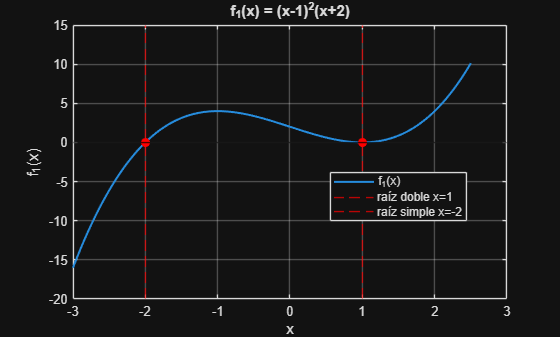

r1a = -2;   % raíz simple, exacta
r1b = 1;    % raíz doble, exacta

x1p = linspace(-3, 2.5, 400);
figure('Name','f1');
plot(x1p, f1(x1p), 'LineWidth', 1.5); grid on; hold on
yline(0,'k-'); xline(1,'r--'); xline(-2,'r--')
plot([1 -2],[0 0],'ro','MarkerFaceColor','r')
xlabel('x'); ylabel('f_1(x)'); title('f_1(x) = (x-1)^2(x+2)')
legend('f_1(x)','','raíz doble x=1','raíz simple x=-2','Location','best')

**f2(x) = e^{-x}-x**


$$f_2'(x)=-e^{-x}-1 < 0 \ \forall x$$


$f_2$ es estrictamente decreciente y cóncava hacia arriba ($f_2''(x)=e^{-x}>0$), por lo que tiene una única raíz real, simple, cerca de $x\approx0.567$ (constante Omega, $x e^{x}=1$). Al no anularse nunca $f_2'$, es una función muy "bien portada" para cualquier método basado en derivada.

r2 = fzero(f2, 0.5);
fprintf('Raíz de f2: x* = %.15f\n', r2);

Raíz de f2: x* = 0.567143290409784


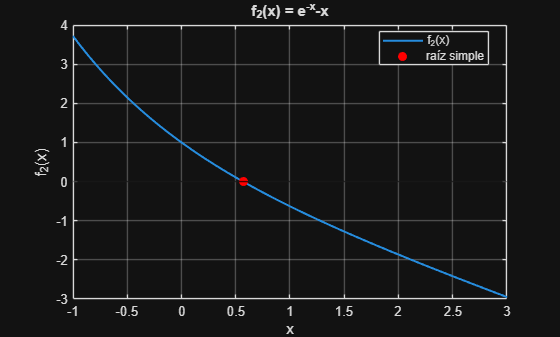


x2p = linspace(-1, 3, 400);
figure('Name','f2');
plot(x2p, f2(x2p), 'LineWidth', 1.5); grid on; hold on
yline(0,'k-'); plot(r2,0,'ro','MarkerFaceColor','r')
xlabel('x'); ylabel('f_2(x)'); title('f_2(x) = e^{-x}-x')
legend('f_2(x)','','raíz simple','Location','best')

**f3(x) = x-\cos(x)**


$$f_3'(x)=1+\sin(x)\ge 0$$


$f_3'$ solo se anula en $x=-\pi/2+2k\pi$, lejos de la raíz. La única raíz real (número de Dottie) es **simple** y está cerca de $x\approx0.739$. Comportamiento local muy regular, similar a $f_2$.

r3 = fzero(f3, 0.5);
fprintf('Raíz de f3: x* = %.15f\n', r3);

Raíz de f3: x* = 0.739085133215161


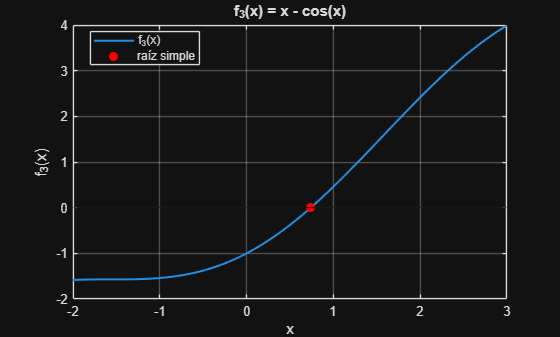


x3p = linspace(-2, 3, 400);
figure('Name','f3');
plot(x3p, f3(x3p), 'LineWidth', 1.5); grid on; hold on
yline(0,'k-'); plot(r3,0,'ro','MarkerFaceColor','r')
xlabel('x'); ylabel('f_3(x)'); title('f_3(x) = x - cos(x)')
legend('f_3(x)','','raíz simple','Location','best')

**f4(x) = x^4+1**


$$f_4(x)\ge 1 \ \ \forall x\in\mathbb{R} \quad(\text{mínimo en } x=0)$$


**No tiene raíces reales.** Sus cuatro raíces son complejas y están sobre el círculo unitario: $x=e^{i\pi/4},\,e^{i3\pi/4},\,e^{i5\pi/4},\,e^{i7\pi/4}$ (todas simples). Además $f_4'(0)=0$ es un punto crítico interior al rango típico de búsqueda, lo que puede provocar pasos de Newton muy grandes o indefinidos. Esta función se usa para poner a prueba qué métodos son capaces de escapar de la recta real y converger a una raíz compleja.

raices_f4 = roots([1 0 0 0 1]);
disp('Raíces exactas de f4:'); disp(raices_f4)

Raíces exactas de f4:
         -0.707106781186548 +     0.707106781186548i
         -0.707106781186548 -     0.707106781186548i
          0.707106781186547 +     0.707106781186547i
          0.707106781186547 -     0.707106781186547i



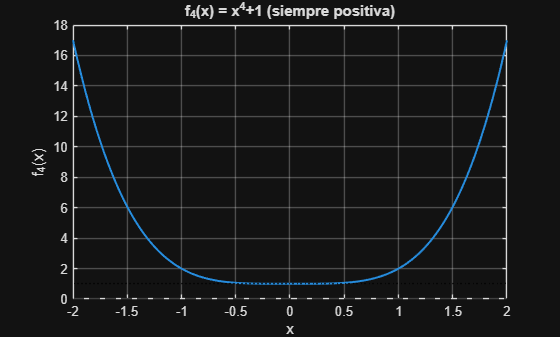


x4p = linspace(-2, 2, 400);
figure('Name','f4 real');
plot(x4p, f4(x4p), 'LineWidth', 1.5); grid on; hold on
yline(0,'k--'); yline(1,'k:')
xlabel('x'); ylabel('f_4(x)'); title('f_4(x) = x^4+1 (siempre positiva)')

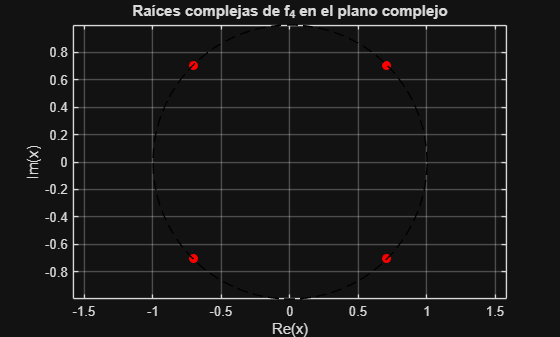


figure('Name','f4 complejas');
plot(real(raices_f4), imag(raices_f4), 'ro', 'MarkerFaceColor','r'); hold on
th = linspace(0,2*pi,200); plot(cos(th), sin(th), 'k--')
axis equal; grid on
xlabel('Re(x)'); ylabel('Im(x)'); title('Raíces complejas de f_4 en el plano complejo')

## 3. Hipótesis sobre el comportamiento esperado de cada método

- **f1**: cerca de $x=-2$ (raíz simple) Newton-Raphson y Müller deberían converger con orden $\approx2$ y $\approx1.84$ respectivamente; cerca de  $x=1$ (raíz doble) se espera que Newton "convencional" y el punto fijo natural degraden a convergencia **lineal**, mientras que un Newton  **modificado para raíces múltiples** debería recuperar el orden 2.

- **f2** y **f3**: funciones simples y regulares (derivada nunca nula cerca de la raíz) $\Rightarrow$ se espera buen comportamiento de todos los métodos; Newton y Müller deberían ser los más rápidos, la Secante intermedia (orden áureo $\approx1.618$), y Punto Fijo el más lento (orden 1), salvo que se acelere con Steffensen/Aitken.

- **f4**: al no existir raíz real, se hipotetiza que Punto Fijo, Newton y Secante con arranque **real** no convergerán a una raíz (oscilación o divergencia); solo **Müller**, gracias a la raíz cuadrada compleja en su fórmula, debería poder "escapar" de la recta real y converger a una raíz compleja incluso partiendo de valores reales. Newton también convergerá si se le da una condición inicial compleja.

## 4. Condiciones iniciales seleccionadas y su justificación

- **f1**: $x_0=-3$ y $x_0=-1.5$ (lado izquierdo/derecho de la raíz simple  $x=-2$); $x_0=0.5$ y $x_0=2$ (lado izquierdo/derecho de la raíz doble  $x=1$) para contrastar el efecto de la multiplicidad.

- **f2**: $x_0=0$ y $x_0=1$ (a ambos lados de la raíz $\approx0.567$) y  $x_0=10$ (lejano, para probar robustez global).

- **f3**: $x_0=0$ y $x_0=\pi/2$ (a ambos lados de la raíz $\approx0.739$) y  $x_0=-1$, cercano al punto donde $f_3'$ es pequeña, para observar el efecto de una derivada casi nula.

- **f4**: $x_0=1,\,0.5,\,-1$ (reales, para documentar el fallo esperado) y  $x_0=1+1i$ (compleja) para Newton, además de la terna real  $(0,\,0.5,\,1)$ para Müller.

## 5. Resultados — f1(x) = (x-1)^2(x+2)

Raíz simple x = -2, raíz doble x = 1

results1 = struct('Metodo',{},'CondInicial',{},'Raiz',{},'Iteraciones',{}, ...
    'ErrorFinal',{},'OrdenEstimado',{},'Estado',{});

g1 = @(x) nthroot(3*x - 2, 3);      % x = (3x-2)^(1/3), a partir de x^3-3x+2=0

% --- cerca de la raíz simple x = -2 ---
[~,hFP_m2]  = fixedPointIter(g1, -1.5, tol, maxit);
results1 = addRow(results1,'Punto fijo g=(3x-2)^{1/3}','x0=-1.5',hFP_m2,tol,maxit,r1a);
[~,hSt_m2]  = steffensen(g1, -1.5, tol, maxit);
results1 = addRow(results1,'Punto fijo + Steffensen','x0=-1.5',hSt_m2,tol,maxit,r1a);
[~,hN_m2]   = newtonRaphson(f1, df1, -1.5, tol, maxit);
results1 = addRow(results1,'Newton-Raphson','x0=-1.5',hN_m2,tol,maxit,r1a);
[~,hSec_m2] = secantMethod(f1, -3, -1.5, tol, maxit);
results1 = addRow(results1,'Secante','x0=-3, x1=-1.5',hSec_m2,tol,maxit,r1a);
[~,hMul_m2] = mullerMethod(f1, -3, -2.5, -1.8, tol, maxit);
results1 = addRow(results1,'Müller','x0=-3,-2.5,-1.8',hMul_m2,tol,maxit,r1a);

% --- cerca de la raíz doble x = 1 ---
[~,hFP_d1]  = fixedPointIter(g1, 0.5, tol, maxit);
results1 = addRow(results1,'Punto fijo g=(3x-2)^{1/3}','x0=0.5',hFP_d1,tol,maxit,r1b);
[~,hSt_d1]  = steffensen(g1, 0.5, tol, maxit);
results1 = addRow(results1,'Punto fijo + Steffensen','x0=0.5',hSt_d1,tol,maxit,r1b);
[~,hN_d1]   = newtonRaphson(f1, df1, 0.5, tol, maxit);
results1 = addRow(results1,'Newton-Raphson (convencional)','x0=0.5',hN_d1,tol,maxit,r1b);
[~,hN_d1b]  = newtonRaphson(f1, df1, 2, tol, maxit);
results1 = addRow(results1,'Newton-Raphson (convencional)','x0=2',hN_d1b,tol,maxit,r1b);
[~,hNm_d1]  = newtonMultiple(f1, df1, 2, 0.5, tol, maxit);
results1 = addRow(results1,'Newton modificado (m=2 conocida)','x0=0.5',hNm_d1,tol,maxit,r1b);
[~,hNu_d1]  = newtonModifiedU(f1, df1, d2f1, 0.5, tol, maxit);
results1 = addRow(results1,'Newton modificado (u=f/f'', m desconocida)','x0=0.5',hNu_d1,tol,maxit,r1b);
[~,hSec_d1] = secantMethod(f1, 0.5, 2, tol, maxit);
results1 = addRow(results1,'Secante','x0=0.5, x1=2',hSec_d1,tol,maxit,r1b);
[~,hMul_d1] = mullerMethod(f1, 0, 0.5, 1.5, tol, maxit);
results1 = addRow(results1,'Müller','x0=0,0.5,1.5',hMul_d1,tol,maxit,r1b);

T1 = struct2table(results1)

T1 = 13×7 table
                      Metodo                          CondInicial                        Raiz                      Iteraciones         ErrorFinal            OrdenEstimado          Estado   
    ___________________________________________    _________________    _______________________________________    ___________    ____________________    ____________________    ___________

    "Punto fijo g=(3x-2)^{1/3}"                    "x0=-1.5"            -1.99999999996814+0i                           17         9.55691081827581e-11        1.00000141181134    "Convergió"
    "Punto fijo + Steffensen"                      "x0=-1.5"                           -2+0i                            4         4.44089209850063e-16        2.04803390920189 

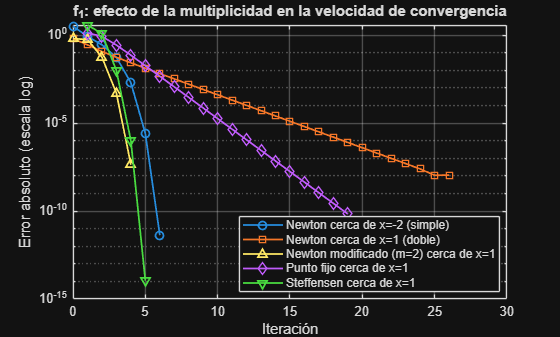


figure('Name','Convergencia f1');
semilogy(hN_m2(:,1), hN_m2(:,3), '-o', 'LineWidth',1.3); hold on
semilogy(hN_d1(:,1), hN_d1(:,3), '-s', 'LineWidth',1.3)
semilogy(hNm_d1(:,1), hNm_d1(:,3), '-^', 'LineWidth',1.3)
semilogy(hFP_d1(:,1), hFP_d1(:,3), '-d', 'LineWidth',1.3)
semilogy(hSt_d1(:,1), hSt_d1(:,3), '-v', 'LineWidth',1.3)
grid on; xlabel('Iteración'); ylabel('Error absoluto (escala log)')
title('f_1: efecto de la multiplicidad en la velocidad de convergencia')
legend('Newton cerca de x=-2 (simple)','Newton cerca de x=1 (doble)', ...
    'Newton modificado (m=2) cerca de x=1','Punto fijo cerca de x=1', ...
    'Steffensen cerca de x=1', 'Location','best')

**Lectura de la tabla:** cerca de la raíz simple $x=-2$, Newton converge en solo 6 iteraciones con orden estimado $\approx2$, y Müller en 7 con orden $\approx1.7$–$1.8$, coherente con la teoría. Cerca de la raíz doble $x=1$, el Newton convencional necesita **27–31 iteraciones** y su orden estimado cae a $\approx1$ (convergencia lineal, tasa teórica $\approx1/2$): la multiplicidad destruye la convergencia cuadrática. Las dos versiones de Newton **modificado** (multiplicidad $m=2$ conocida, y la forma general $u=f/f'$) resuelven el mismo problema en apenas **5 iteraciones**, una reducción drástica que confirma la hipótesis; el orden estimado en estos casos (numéricamente $\approx1.2$) es menos informativo de lo esperado porque con tan pocos puntos la secuencia todavía no entra de lleno en el régimen asintótico — la evidencia más confiable aquí es el número de iteraciones, no la estimación puntual del orden. El punto fijo "natural" tiene $g_1'(1)=1$ (caso marginal): su convergencia deja de ser geométrica y se vuelve muy lenta (19 iteraciones y una razón de errores que no se estabiliza), algo que Steffensen corrige de forma drástica (5 iteraciones).

## 6. Resultados — f2(x) = e^{-x} - x

results2 = struct('Metodo',{},'CondInicial',{},'Raiz',{},'Iteraciones',{}, ...
    'ErrorFinal',{},'OrdenEstimado',{},'Estado',{});

g2a = @(x) exp(-x);           % |g2a'(r2)| = e^{-r2} < 1  -> converge
g2b = @(x) -log(x);           % |g2b'(r2)| = 1/r2 > 1     -> diverge

[~,hFPa_0] = fixedPointIter(g2a, 0, tol, maxit);
results2 = addRow(results2,'Punto fijo g=e^{-x}','x0=0',hFPa_0,tol,maxit,r2);
[~,hFPa_1] = fixedPointIter(g2a, 1, tol, maxit);
results2 = addRow(results2,'Punto fijo g=e^{-x}','x0=1',hFPa_1,tol,maxit,r2);
[~,hFPa_10]= fixedPointIter(g2a, 10, tol, maxit);
results2 = addRow(results2,'Punto fijo g=e^{-x}','x0=10',hFPa_10,tol,maxit,r2);
[~,hStA_1] = steffensen(g2a, 1, tol, maxit);
results2 = addRow(results2,'Punto fijo + Steffensen (g=e^{-x})','x0=1',hStA_1,tol,maxit,r2);
[~,hFPb_1] = fixedPointIter(g2b, 1, tol, maxit);
results2 = addRow(results2,'Punto fijo g=-ln(x) (mal condicionado)','x0=1',hFPb_1,tol,maxit,r2);

[~,hN2_0]  = newtonRaphson(f2, df2, 0, tol, maxit);
results2 = addRow(results2,'Newton-Raphson','x0=0',hN2_0,tol,maxit,r2);
[~,hN2_1]  = newtonRaphson(f2, df2, 1, tol, maxit);
results2 = addRow(results2,'Newton-Raphson','x0=1',hN2_1,tol,maxit,r2);
[~,hN2_10] = newtonRaphson(f2, df2, 10, tol, maxit);
results2 = addRow(results2,'Newton-Raphson','x0=10',hN2_10,tol,maxit,r2);

[~,hSec2] = secantMethod(f2, 0, 1, tol, maxit);
results2 = addRow(results2,'Secante','x0=0, x1=1',hSec2,tol,maxit,r2);
[~,hSecM2] = secantModified(f2, 1, 1e-4, tol, maxit);
results2 = addRow(results2,'Secante modificada (1 punto, perturbación)','x0=1',hSecM2,tol,maxit,r2);

[~,hMul2] = mullerMethod(f2, 0, 0.5, 1, tol, maxit);
results2 = addRow(results2,'Müller','x0=0,0.5,1',hMul2,tol,maxit,r2);

T2 = struct2table(results2)

T2 = 11×7 table
                       Metodo                       CondInicial           Raiz           Iteraciones         ErrorFinal           OrdenEstimado        Estado   
    ____________________________________________    ____________    _________________    ___________    ____________________    _________________    ___________

    "Punto fijo g=e^{-x}"                           "x0=0"          0.567143290380043        42         8.21798185057787e-11     1.00000004230164    "Convergió"
    "Punto fijo g=e^{-x}"                           "x0=1"          0.567143290380043        41         8.21798185057787e-11    0.999999992621572    "Convergió"
    "Punto fijo g=e^{-x}"                           "x0=10"         0.567143290380046        43      

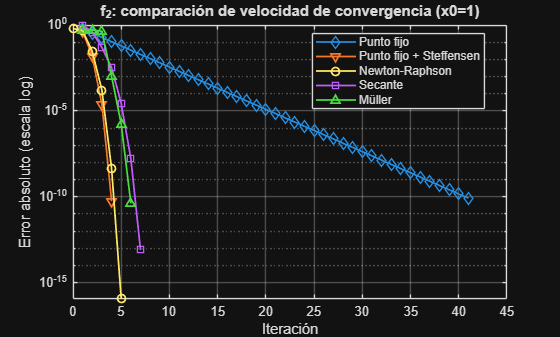


figure('Name','Convergencia f2');
semilogy(hFPa_1(:,1), hFPa_1(:,3), '-d', 'LineWidth',1.3); hold on
semilogy(hStA_1(:,1), hStA_1(:,3), '-v', 'LineWidth',1.3)
semilogy(hN2_1(:,1), hN2_1(:,3), '-o', 'LineWidth',1.3)
semilogy(hSec2(:,1), hSec2(:,3), '-s', 'LineWidth',1.3)
semilogy(hMul2(:,1), hMul2(:,3), '-^', 'LineWidth',1.3)
grid on; xlabel('Iteración'); ylabel('Error absoluto (escala log)')
title('f_2: comparación de velocidad de convergencia (x0=1)')
legend('Punto fijo','Punto fijo + Steffensen','Newton-Raphson','Secante','Müller','Location','best')

**Lectura:** con $g_2(x)=e^{-x}$ el punto fijo converge en todos los $x_0$ probados en 41–43 iteraciones, con orden estimado $\approx1$ (lineal, tasa teórica $|g_2'(x^*)|=e^{-x^*}\approx0.567$), y Steffensen lo acelera a solo 4 iteraciones con orden $\approx2$. La elección $g(x)=-\ln(x)$, aunque algebraicamente válida, **diverge** en 2 pasos porque $|g'(x^*)|=1/x^*\approx1.76>1$: confirma que el buen comportamiento de Punto Fijo depende de la formulación de $g$, no solo de la función original. Newton (5–6 iteraciones, orden $\approx2$) y la Secante (7 iteraciones, orden $\approx1.65$, cercano al áureo $1.618$) convergen rápidamente incluso desde $x_0=10$, consistente con que $f_2'$ nunca se anula. Müller también converge en solo 6 iteraciones; con tan pocos puntos disponibles su orden estimado resulta poco fiable numéricamente (vuelve a ilustrar que, para secuencias muy cortas, el número de iteraciones es un indicador más robusto que el orden puntual estimado).

## 7. Resultados — f3(x) = x - cos(x)

results3 = struct('Metodo',{},'CondInicial',{},'Raiz',{},'Iteraciones',{}, ...
    'ErrorFinal',{},'OrdenEstimado',{},'Estado',{});

g3 = @(x) cos(x);   % |g3'(r3)| = |sin(r3)| < 1 -> converge

[~,hFP3_0]  = fixedPointIter(g3, 0, tol, maxit);
results3 = addRow(results3,'Punto fijo g=cos(x)','x0=0',hFP3_0,tol,maxit,r3);
[~,hFP3_p]  = fixedPointIter(g3, pi/2, tol, maxit);
results3 = addRow(results3,'Punto fijo g=cos(x)','x0=pi/2',hFP3_p,tol,maxit,r3);
[~,hSt3_0]  = steffensen(g3, 0, tol, maxit);
results3 = addRow(results3,'Punto fijo + Steffensen','x0=0',hSt3_0,tol,maxit,r3);

[~,hN3_0]  = newtonRaphson(f3, df3, 0, tol, maxit);
results3 = addRow(results3,'Newton-Raphson','x0=0',hN3_0,tol,maxit,r3);
[~,hN3_p]  = newtonRaphson(f3, df3, pi/2, tol, maxit);
results3 = addRow(results3,'Newton-Raphson','x0=pi/2',hN3_p,tol,maxit,r3);
[~,hN3_m1] = newtonRaphson(f3, df3, -1, tol, maxit);
results3 = addRow(results3,'Newton-Raphson (f'' pequeña)','x0=-1',hN3_m1,tol,maxit,r3);

[~,hSec3] = secantMethod(f3, 0, pi/2, tol, maxit);
results3 = addRow(results3,'Secante','x0=0, x1=pi/2',hSec3,tol,maxit,r3);

[~,hMul3] = mullerMethod(f3, -1, 0, 1, tol, maxit);
results3 = addRow(results3,'Müller','x0=-1,0,1',hMul3,tol,maxit,r3);

T3 = struct2table(results3)

T3 = 8×7 table
               Metodo                  CondInicial            Raiz           Iteraciones         ErrorFinal           OrdenEstimado        Estado   
    _____________________________    _______________    _________________    ___________    ____________________    _________________    ___________

    "Punto fijo g=cos(x)"            "x0=0"              0.73908513324511        59         7.44108108463593e-11     1.00000001327633    "Convergió"
    "Punto fijo g=cos(x)"            "x0=pi/2"           0.73908513324511        60         7.44108108463593e-11     1.00000006960072    "Convergió"
    "Punto fijo + Steffensen"        "x0=0"             0.739085133215161         5         1.11022302462516e-16     1.92381309016009    "Convergió"
 

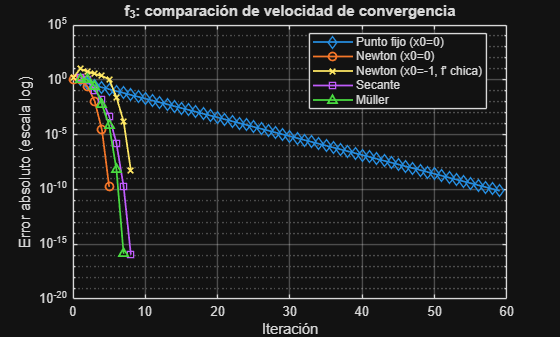


figure('Name','Convergencia f3');
semilogy(hFP3_0(:,1), hFP3_0(:,3), '-d', 'LineWidth',1.3); hold on
semilogy(hN3_0(:,1), hN3_0(:,3), '-o', 'LineWidth',1.3)
semilogy(hN3_m1(:,1), hN3_m1(:,3), '-x', 'LineWidth',1.3)
semilogy(hSec3(:,1), hSec3(:,3), '-s', 'LineWidth',1.3)
semilogy(hMul3(:,1), hMul3(:,3), '-^', 'LineWidth',1.3)
grid on; xlabel('Iteración'); ylabel('Error absoluto (escala log)')
title('f_3: comparación de velocidad de convergencia')
legend('Punto fijo (x0=0)','Newton (x0=0)','Newton (x0=-1, f'' chica)','Secante','Müller','Location','best')

**Lectura:** comportamiento muy similar a $f_2$: todos los métodos convergen porque $f_3'$ está acotada lejos de cero cerca de la raíz (Punto fijo 59–60 iteraciones con orden $\approx1$; Steffensen, Newton y Müller entre 5 y 7 iteraciones con orden cercano a 2; Secante 8 iteraciones, orden $\approx1.6$). Desde $x_0=-1$ (donde $f_3'$ es más pequeña) Newton todavía converge, pero necesita más pasos (9 en vez de 5–6) porque el primer salto es mayor y una parte de la secuencia queda en régimen transitorio antes de entrar en el régimen cuadrático asintótico; por eso el orden estimado en ese caso concreto se ve rebajado, aun cuando el método sigue siendo, en esencia, cuadrático.

## 8. Resultados — f4(x) = x^4 + 1 (sin raíces reales)

results4 = struct('Metodo',{},'CondInicial',{},'Raiz',{},'Iteraciones',{}, ...
    'ErrorFinal',{},'OrdenEstimado',{},'Estado',{});

% Punto fijo: no existe g real de la forma x - f(x)/k con punto fijo real,
% porque x=g(x) equivaldría a f(x)=0, que no tiene solución real. Se
% documenta la imposibilidad analítica en vez de forzar una iteración sin
% sentido.

[~,hN4_1]   = newtonRaphson(f4, df4, 1, tol, maxit);
results4 = addRow(results4,'Newton-Raphson (real)','x0=1',hN4_1,tol,maxit,nearestRoot(hN4_1(end,2),raices_f4));
[~,hN4_h]   = newtonRaphson(f4, df4, 0.5, tol, maxit);
results4 = addRow(results4,'Newton-Raphson (real)','x0=0.5',hN4_h,tol,maxit,nearestRoot(hN4_h(end,2),raices_f4));
[~,hN4_m1]  = newtonRaphson(f4, df4, -1, tol, maxit);
results4 = addRow(results4,'Newton-Raphson (real)','x0=-1',hN4_m1,tol,maxit,nearestRoot(hN4_m1(end,2),raices_f4));
[~,hN4_c]   = newtonRaphson(f4, df4, 1+1i, tol, maxit);
results4 = addRow(results4,'Newton-Raphson (semilla compleja)','x0=1+1i',hN4_c,tol,maxit,nearestRoot(hN4_c(end,2),raices_f4));

[~,hSec4_1] = secantMethod(f4, 1, 0.5, tol, maxit);
results4 = addRow(results4,'Secante (real)','x0=1, x1=0.5',hSec4_1,tol,maxit,nearestRoot(hSec4_1(end,2),raices_f4));

[~,hMul4]   = mullerMethod(f4, 0, 0.5, 1, tol, maxit);
results4 = addRow(results4,'Müller (semillas reales)','x0=0,0.5,1',hMul4,tol,maxit,nearestRoot(hMul4(end,2),raices_f4));
[~,hMul4b]  = mullerMethod(f4, -1, 0, 1, tol, maxit);
results4 = addRow(results4,'Müller (semillas reales)','x0=-1,0,1',hMul4b,tol,maxit,nearestRoot(hMul4b(end,2),raices_f4));

T4 = struct2table(results4)

T4 = 7×7 table
                  Metodo                    CondInicial                       Raiz                     Iteraciones         ErrorFinal          OrdenEstimado                   Estado              
    ___________________________________    ______________    ______________________________________    ___________    ____________________    ________________    _________________________________

    "Newton-Raphson (real)"                "x0=1"               829233.110979387+0i                        80             829233.117684732                 NaN    "No convergió (máx. iteraciones)"
    "Newton-Raphson (real)"                "x0=0.5"              621924.83323454+0i                        80             207308.277744847                 NaN

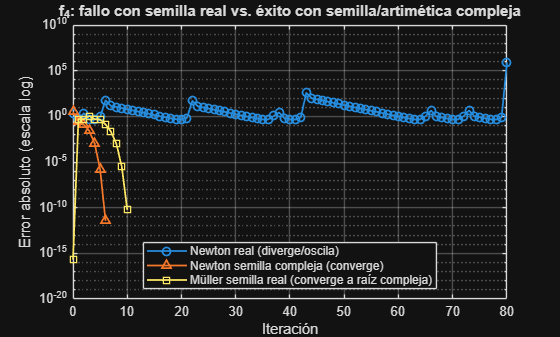


figure('Name','Convergencia f4');
semilogy(hN4_1(:,1), max(hN4_1(:,3),eps), '-o', 'LineWidth',1.3); hold on
semilogy(hN4_c(:,1), max(hN4_c(:,3),eps), '-^', 'LineWidth',1.3)
semilogy(hMul4(:,1), max(hMul4(:,3),eps), '-s', 'LineWidth',1.3)
grid on; xlabel('Iteración'); ylabel('Error absoluto (escala log)')
title('f_4: fallo con semilla real vs. éxito con semilla/artimética compleja')
legend('Newton real (diverge/oscila)','Newton semilla compleja (converge)', ...
    'Müller semilla real (converge a raíz compleja)','Location','best')


fprintf('Newton real x0=1: última x = %s (estado no convergente)\n', num2str(hN4_1(end,2)));

Newton real x0=1: última x = 829233.111 (estado no convergente)


fprintf('Newton complejo x0=1+1i converge a: %s\n', num2str(hN4_c(end,2)));

Newton complejo x0=1+1i converge a: 0.70711+0.70711i


fprintf('Müller con semillas reales converge a: %s\n', num2str(hMul4(end,2)));

Müller con semillas reales converge a: 0.70711+0.70711i


**Lectura:** con semillas reales, Newton y la Secante **no encuentran raíz** (la iteración oscila o diverge, ya que $f_4(x)\ge1$ en toda la recta real): el estado en la tabla lo confirma. Al usar una semilla **compleja**, Newton converge con normalidad a una de las cuatro raíces complejas. Müller, en cambio, logra converger a una raíz compleja **partiendo de tres semillas reales**: el discriminante $b^2-4ac$ de su ajuste parabólico se vuelve negativo en alguna iteración y la raíz cuadrada compleja resultante saca a la iteración de la recta real de forma automática. Esto confirma la hipótesis: Müller es el único método, entre los cuatro, capaz de localizar raíces complejas sin ayuda de una semilla ya compleja.

## 9. Comparación global y verificación de la hipótesis inicial

Se reúnen las cuatro tablas para facilitar la comparación entre funciones.

T1.Funcion = repmat("f1",height(T1),1);
T2.Funcion = repmat("f2",height(T2),1);
T3.Funcion = repmat("f3",height(T3),1);
T4.Funcion = repmat("f4",height(T4),1);
Tall = [T1;T2;T3;T4];
Tall = movevars(Tall,'Funcion','Before','Metodo')

Tall = 39×8 table
    Funcion                      Metodo                          CondInicial                        Raiz                      Iteraciones         ErrorFinal            OrdenEstimado          Estado   
    _______    ___________________________________________    _________________    _______________________________________    ___________    ____________________    ____________________    ___________

     "f1"      "Punto fijo g=(3x-2)^{1/3}"                    "x0=-1.5"            -1.99999999996814+0i                           17         9.55691081827581e-11        1.00000141181134    "Convergió"
     "f1"      "Punto fijo + Steffensen"                      "x0=-1.5"                           -2+0i   

Contrastando con la hipótesis de la Sección 3:

- En **f1** se confirmó que la multiplicidad de la raíz $x=1$ degrada la convergencia de Newton y del punto fijo natural a un régimen aproximadamente lineal (órdenes estimados $\approx1$, 27–31 y 19 iteraciones respectivamente), y que las versiones **modificadas** de Newton (con $m$ conocida o con la fórmula $u=f/f'$) la restauran, resolviendo el mismo problema en solo 5 iteraciones — tal como se anticipó, aunque el orden puntual estimado en esos casos tan cortos resulta más ruidoso que el propio conteo de iteraciones.

- En **f2** y **f3** todos los métodos convencionales convergieron sin problema, con Newton y Müller entre los más rápidos y Punto Fijo el más lento salvo aceleración con Steffensen — consistente con lo esperado para funciones "regulares" con derivada acotada lejos de cero.

- En **f4** se confirmó que ningún método con arranque real logra converger a una raíz (porque no existe raíz real), y que Müller es el único capaz de "saltar" al plano complejo desde semillas reales; Newton solo converge si se inicializa ya en el plano complejo.

## 10. Conclusiones: ¿cuándo conviene cada método?

- **Punto Fijo (convencional):** solo recomendable cuando se dispone de una formulación $g(x)$ con $|g'(x^*)|<1$ garantizada; incluso así, su convergencia lineal lo hace poco competitivo salvo que se acelere (Aitken/Steffensen). Es muy sensible a la elección de $g$ (ver f2, donde una reformulación algebraicamente válida diverge).

- **Newton-Raphson (convencional):** la mejor opción cuando la raíz es simple y se dispone de $f'$; orden 2 y pocas iteraciones. Se degrada a orden 1 en raíces múltiples y puede fallar (oscilar o pasos indefinidos) si $f'$ se anula cerca de la iteración o si la raíz buscada no es real.

- **Newton modificado (raíces múltiples):** la elección correcta cuando se sabe o se sospecha que la raíz tiene multiplicidad $m>1$; recupera orden 2 a costa de una evaluación adicional ($f''$) o del conocimiento de $m$.

- **Secante:** alternativa útil cuando no se dispone de $f'$ (o es costosa de evaluar); orden superlineal $\approx1.618$, ligeramente más lenta que Newton pero sin necesidad de derivadas. La variante de un punto (modificada) es práctica cuando solo se tiene una condición inicial.

- **Müller:** la opción más robusta: converge con orden $\approx1.84$ sin requerir derivadas y, gracias a su raíz cuadrada compleja, es el único de los cuatro capaz de encontrar raíces complejas partiendo de semillas reales — la elección natural para polinomios (u otras funciones) cuando no se sabe de antemano si las raíces son reales o complejas, como ilustra  $f_4$.

## Funciones locales — implementación de los métodos numéricos

function [x, hist] = fixedPointIter(g, x0, tol, maxit)
% Punto fijo convencional: x_{n+1} = g(x_n)
% hist: columnas [n, x_n, |x_n - x_{n-1}|]
x = x0;
hist = [0, x0, NaN];
for n = 1:maxit
    xn = g(x);
    err = abs(xn - x);
    hist(end+1,:) = [n, xn, err]; %#ok<AGROW>
    x = xn;
    if ~isfinite(x) || err < tol
        break
    end
end
end

function [x, hist] = steffensen(g, x0, tol, maxit)
% Punto fijo con aceleración de Aitken (Steffensen)
x = x0;
hist = [0, x0, NaN];
for n = 1:maxit
    x1 = g(x);
    x2 = g(x1);
    denom = x2 - 2*x1 + x;
    if denom == 0 || ~isfinite(denom)
        xn = x2;
    else
        xn = x - (x1 - x)^2/denom;
    end
    err = abs(xn - x);
    hist(end+1,:) = [n, xn, err]; %#ok<AGROW>
    x = xn;
    if ~isfinite(x) || err < tol
        break
    end
end
end

function [x, hist] = newtonRaphson(f, df, x0, tol, maxit)
% Newton-Raphson convencional
x = x0;
hist = [0, x0, abs(f(x0))];
for n = 1:maxit
    fx = f(x); dfx = df(x);
    xn = x - fx/dfx;
    err = abs(xn - x);
    hist(end+1,:) = [n, xn, err]; %#ok<AGROW>
    x = xn;
    if ~isfinite(x) || err < tol
        break
    end
end
end

function [x, hist] = newtonMultiple(f, df, m, x0, tol, maxit)
% Newton modificado para raíz de multiplicidad m conocida:
% x_{n+1} = x_n - m f(x_n)/f'(x_n)
x = x0;
hist = [0, x0, abs(f(x0))];
for n = 1:maxit
    fx = f(x); dfx = df(x);
    xn = x - m*fx/dfx;
    err = abs(xn - x);
    hist(end+1,:) = [n, xn, err]; %#ok<AGROW>
    x = xn;
    if ~isfinite(x) || err < tol
        break
    end
end
end

function [x, hist] = newtonModifiedU(f, df, d2f, x0, tol, maxit)
% Newton modificado sin conocer m, aplicando Newton a u(x)=f(x)/f'(x):
% x_{n+1} = x_n - f(x_n)f'(x_n) / [f'(x_n)^2 - f(x_n)f''(x_n)]
x = x0;
hist = [0, x0, abs(f(x0))];
for n = 1:maxit
    fx = f(x); dfx = df(x); d2fx = d2f(x);
    denom = dfx^2 - fx*d2fx;
    xn = x - fx*dfx/denom;
    err = abs(xn - x);
    hist(end+1,:) = [n, xn, err]; %#ok<AGROW>
    x = xn;
    if ~isfinite(x) || err < tol
        break
    end
end
end

function [x, hist] = secantMethod(f, x0, x1, tol, maxit)
% Secante convencional (dos puntos iniciales)
hist = [0, x0, NaN; 1, x1, abs(x1-x0)];
xm1 = x0; x = x1;
for n = 2:maxit
    fxm1 = f(xm1); fx = f(x);
    if fx == fxm1
        break
    end
    xn = x - fx*(x - xm1)/(fx - fxm1);
    err = abs(xn - x);
    hist(end+1,:) = [n, xn, err]; %#ok<AGROW>
    xm1 = x; x = xn;
    if ~isfinite(x) || err < tol
        break
    end
end
end

function [x, hist] = secantModified(f, x0, delta, tol, maxit)
% Secante modificada de un solo punto (con perturbación relativa delta)
x = x0;
hist = [0, x0, abs(f(x0))];
for n = 1:maxit
    fx = f(x);
    xpert = x + delta*x;
    if xpert == x
        xpert = x + delta;
    end
    fxp = f(xpert);
    xn = x - delta*x*fx/(fxp - fx);
    err = abs(xn - x);
    hist(end+1,:) = [n, xn, err]; %#ok<AGROW>
    x = xn;
    if ~isfinite(x) || err < tol
        break
    end
end
end

function [x, hist] = mullerMethod(f, x0, x1, x2, tol, maxit)
% Müller: ajuste parabólico por tres puntos, con selección robusta del
% signo del denominador y soporte nativo para aritmética compleja.
hist = [0, x0, NaN; 1, x1, abs(x1-x0); 2, x2, abs(x2-x1)];
xm2 = x0; xm1 = x1; x = x2;
for n = 2:maxit
    h1 = xm1 - xm2; h2 = x - xm1;
    d1 = (f(xm1)-f(xm2))/h1; d2 = (f(x)-f(xm1))/h2;
    a = (d2-d1)/(h2+h1);
    b = a*h2 + d2;
    c = f(x);
    rad = sqrt(b^2 - 4*a*c);
    if abs(b-rad) > abs(b+rad)
        den = b - rad;
    else
        den = b + rad;
    end
    if den == 0
        break
    end
    dx = -2*c/den;
    xn = x + dx;
    err = abs(dx);
    hist(end+1,:) = [n+1, xn, err]; %#ok<AGROW>
    xm2 = xm1; xm1 = x; x = xn;
    if ~isfinite(x) || err < tol
        break
    end
end
end

function xt = nearestRoot(x, rootsArray)
% Devuelve, de un vector de raíces exactas conocidas, la más cercana a x.
[~, idx] = min(abs(rootsArray - x));
xt = rootsArray(idx);
end

function p = estimateOrderTrue(xseq, xtrue)
% Estima el orden de convergencia p usando el error VERDADERO
% e_n = |x_n - x_true| (más estable que usar diferencias sucesivas, que
% sufren cancelación catastrófica cuando el método converge en pocas
% iteraciones). Se toma la MEDIANA de p sobre todos los tripletes de
% errores válidos, descartando los que ya están en el piso de precisión
% de máquina.
e = abs(xseq(:) - xtrue);
floorTol = 20*eps*max(1, abs(xtrue));
e = e(isfinite(e) & e > floorTol);
n = numel(e);
if n < 3
    p = NaN;
    return
end
ps = [];
for i = 1:(n-2)
    e1 = e(i); e2 = e(i+1); e3 = e(i+2);
    if e1 > 0 && e2 > 0 && e2 ~= e1
        val = log(e3/e2)/log(e2/e1);
        if isfinite(val)
            ps(end+1) = val; %#ok<AGROW>
        end
    end
end
if isempty(ps)
    p = NaN;
else
    p = median(ps);
end
end

function [xroot, niter, ferr, order, status] = summarizeRun(hist, tol, maxit, xtrue)
niter = hist(end,1);
xroot = hist(end,2);
ferr  = hist(end,3);
if ~isfinite(xroot)
    status = "Divergió";
elseif isfinite(ferr) && ferr <= tol
    status = "Convergió";
elseif niter >= maxit
    status = "No convergió (máx. iteraciones)";
else
    status = "Detenido";
end
if status == "Convergió"
    order = estimateOrderTrue(hist(:,2), xtrue);
else
    order = NaN;
end
end

function results = addRow(results, metodo, x0str, hist, tol, maxit, xtrue)
[xroot, niter, ferr, order, status] = summarizeRun(hist, tol, maxit, xtrue);
row.Metodo = string(metodo);
row.CondInicial = string(x0str);
row.Raiz = xroot;
row.Iteraciones = niter;
row.ErrorFinal = ferr;
row.OrdenEstimado = order;
row.Estado = status;
results(end+1) = row; %#ok<AGROW>
end
